# 1. **Introduction to Optimisation**

## **1.1 What is Optimisation?**

- Optimisation deals with the following problem – choose the value x such that some quantity F, which depends on x, is a ***minimum***. Here, F is referred to as the ***objective function***.

- In mathematical terms, we express this problem as: $\min_{x} F(x)$

- In seeking the minimum of $F(x)$ we may often be restricted in the choice of $x$. Typically, there may be other quantities $C_i(x)$  whose value must be maintained within certain limits. These are called ***constraints***. 

- The variable $x$ may be a scalar or an n-vector (i.e. $\textbf{x} = [x_1 \quad x_2 \quad  \cdots \quad x_n ]^T$). 

- Notice that vectors are represented with bold font, while scalars are not. Also, matrices are generally represented with bold capital font. Alternatively, vectors can be represented using an underline, i.e. $\underline{x}$.

- Hence, the full expression of the problem in standard form is as follows:

            
$$\min \qquad F(\textbf{x}), \textbf{x} \in \Re^n$$


            $\mathrm{subject}\quad \mathrm{to} \qquad C_i(\textbf{x})=0; i=1,2 \cdots ,k$                     (equality constraints)

                                     $C_j(\textbf{x})\geq 0; j=k+1,k+2 \cdots ,m$       (inequality constraints)

            where $m$ represents the total number of constraints.

- Note that if $m=0$, then we are dealing with an ***unconstrained*** optimisation problem, otherwise, if $m \neq 0$, then we have a ***constrained ***optimisation problem.

- Furthermore, note that the ***maximum*** of a function $F(\textbf{x})$ is the same as the minimum of the negative of the function, i.e. – $F(\textbf{x})$. In other words:

            
$$\max F(\textbf{x})\equiv \min (-F(\textbf{x}))
$$


            
$$C_i(\textbf{x})\leq 0 \equiv -C_i(\textbf{x})\geq 0$$


### **Engineering Examples of Optimisation**

- In its broadest sense, optimisation can be applied to solve almost any (if not all) engineering problems.

- Some typical applications that use optimisation include:

- Design of aircraft and aerospace structures for minimum weight.

- Design of water resources systems for maximum benefit.

- Design of pumps, turbines and heat transfer equipment for maximum efficiency.

- Optimal design of electrical networks.

- Selection of a site for an industry.

- Analysis of statistical data and building empirical models from experimental results to obtain the most accurate representation of the physical phenomenon.

- Allocation of resources or services among several activities to maximise benefit.

- Controlling the waiting and idle times and queueing in production lines to reduce the costs.

- Optimum design of control systems.

- *These example applications clearly illustrate the wide scope of optimisation!*

### **An Optimisation Example**

- Consider the function $F(x) = (x^3 - 3x^2)^{\frac{1}{3}}$, where $x
$ is a scalar value (i.e. n = 1 in terms of the vector **x**


syms x;

% Define the function
F = (x^3 - 3*x^2)^(1/3);

% Compute the first derivative and solve for critical points
F_prime = diff(F, x);
crit_points = double(solve(F_prime, x));

% Compute the second derivative
F_double_prime = diff(F_prime, x);

% Analyze the nature of critical points
for point = crit_points'
    if double(subs(F_double_prime, x, point)) > 0
        fprintf('x = %f is a local minimum.\n', point);
    end
end

% Determine global minimum
[min_value, min_index] = min(double(subs(F, x, crit_points)));
global_min_point = crit_points(min_index);

fprintf('The global minimum of F(x) occurs at x = %f with a value of %f\n', global_min_point, min_value);

The global minimum of F(x) occurs at x = 2.000000 with a value of 0.793701


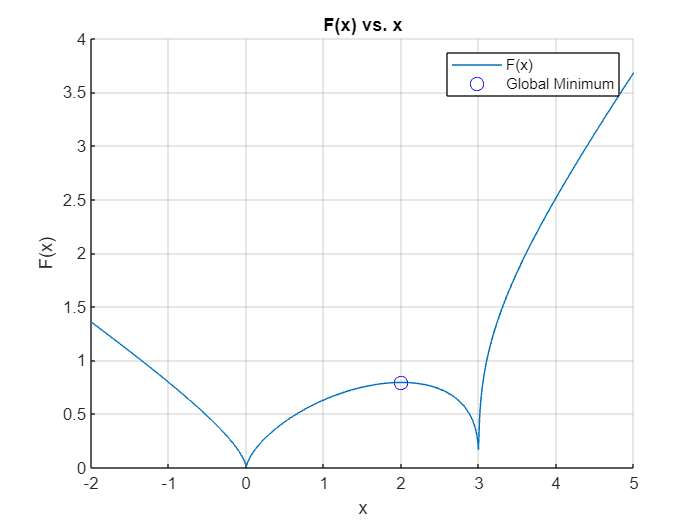

x_values = linspace(-2, 5, 1000);
F_values = double(subs(F, x, x_values));
% Create plot of x_values and F_values
hold on
h = plot(x_values,real(F_values),"DisplayName","F_values");

% Add xlabel, ylabel, title, and legend
xlabel("x_values")
ylabel("F_values")
title("F_values vs. x_values")
% Highlight the global minimum with a blue circle
plot(global_min_point, real(min_value), 'bo', 'MarkerSize', 8, 'DisplayName', 'Global Minimum');
legend

xlim([-2.00 5.00])
ylim([0.00 4.00])
grid on
legend(["F(x)","Global Minimum"])
title("F(x) vs. x")
xlabel("x")
ylabel("F(x)")

- If we apply constraints so that x must lie in the range -0.5 to 4, then our optimisation problem can be stated as:

            
$$\min _{ x \in \Re^1} = (x^3 - 3x^2)^{\frac{1}{3}} $$


            subject to $(x+0.5) \geq 0 $  and $(-x +4)\geq0$

syms x;
F_sym = (x^3 - 3*x^2)^(1/3);
% Objective function
F = @(x) (x^3 - 3*x^2)^(1/3);

% Range of x
x_lower_bound = -0.5;
x_upper_bound = 4;

% Find the minimum within the specified range
[x_min, F_min] = fminbnd(F, x_lower_bound, x_upper_bound);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.003179 




% Display results
fprintf('The minimum value of F(x) within the range is: %f\n', F_min);

The minimum value of F(x) within the range is: 0.003179


fprintf('This occurs at x = %f\n', x_min);

This occurs at x = 0.000293


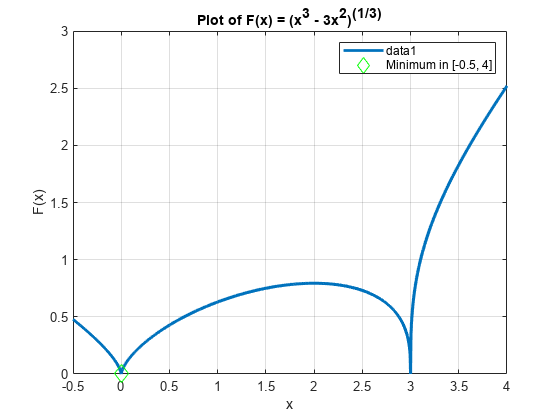


% Define a range of x-values for plotting, e.g., from -0.5 to 4
x_values = linspace(-0.5, 4, 1000);
F_values = double(subs(F_sym, x, x_values));

% Plot F(x) vs. x
figure;
plot(x_values, real(F_values), 'LineWidth', 2);
title('Plot of F(x) = (x^3 - 3x^2)^{(1/3)}');
xlabel('x');
ylabel('F(x)');
grid on;
hold on;

% Highlight the minimum within the constrained range with a green diamond
plot(x_min, real(F_min), 'gd', 'MarkerSize', 10, 'DisplayName', 'Minimum in [-0.5, 4]');
legend show;

xlim([-0.50 4.00])
ylim([0.00 3.00])

- This example illustrates some of the usual features of optimisation problems.

- They are nonlinear and constraints may or may not exist.

- It is worth noting that in this example, the equation of $$F(x)$$ was known. 

- In general, it may or may not be possible to express the objective function $$F(x)$$ and the constraints $$C_i(x)$$ analytically. However, this is okay, as it is only necessary that these functions can be computed for any given value of **x**.

- Analytical solutions are hardly ever available and so iterative methods are used.

## **1.1 Fundamental Principles**

- Consider the following arbitrary graph, where all points shown are stationary points, i.e. the differential of the function at these points is zero.

                        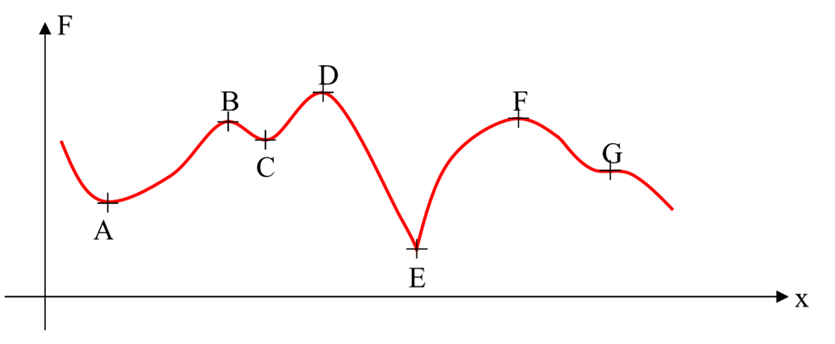

- The points A, C and E are all ***local*** minima. Each has a lower function value than any other point in its own neighbourhood. In mathematical terms, a local minimum **x*** exists for some small value $$\delta$$ if:

                        $F(x^*)\leq F(x) $  for all **x **such that $$||x - x^* ||< \delta$$.

-     The point E is the ***global ***minimum in the range shown. In mathematical terms, a global minimum **x*** exists if:

                        $$F(x^*)\leq F(x)$$ for all **x**.

- Points B, D and F are all local maxima, with D being the global maximum in the range shown.

- Finally, point G is referred to as a point of inflexion.

- For this course, we make the following assumptions in relation to F(x):

-  Continuous

-  Smooth – i.e. its first and second derivatives are continuous (i.e. point E can’t occur!)

-  Single valued and dependent for every value of $$x$$, i.e. for each value of $$x$$ there is one and only one corresponding value of $$F(x)$$.

###  **Basic optimality condition – 1 variable**

- Let $x^*$ denote the value of x at a local minimum. 

- Consider any value of $x$ near $x^*$, i.e. $x = x^* + h$, where $h$ is sufficiently small. Using Taylor’s Theorem we obtain the following expansion:

                
$$F(x^*+h)=F(x^*)+h\left. \frac{dF}{dx} \right|_{x^*} + \frac{1}{2}h^2 \left. \frac{d^2F}{dx^2} \right|_{x^*} + \cdots$$


- Therefore:

                
$$F(x^*+h)-F(x^*)=h\left. \frac{dF}{dx} \right|_{x^*} + \frac{1}{2}h^2\left. \frac{d^2F}{dx^2} \right|_{x^*} + \cdots$$


- We know that $F(x^*+h)-F(x^*)>0$ for a local minimum at $x^*$ given that $|h|$, i.e. $|x-x^*|$, is sufficiently small.

- Furthermore, we know that the first derivative at a minimum (or maximum) is zero.

- Therefore, **a sufficient condition for a local minimum **is:

                $\left. \frac{dF}{dx} \right|_{x^*} = 0$ and $\left. \frac{d^2F}{dx^2} \right|_{x^*} > 0$

- Note that a global minimum is also a local minimum but there is no local criterion for verifying it. We would need to compare all local minimum points to determine which one is the global minimum in the range examined!

- **Example** - determine the minimum point for the function $f(x) = 3x^3+9x^2-4$

                        
$$f(x) = 3x^3+9x^2-4\\
f' = 9x^2 + 18x =0 \rightarrow x=0 ; x=-2$$
 

                        and $f''(x) = 18x+18$

- At $x=0, f''(x)=18>0$ which means that there’s a minimum point at $x=0$.

- At $x=-2, f''(x)=-18 <0$ which means that the point $x=-2$  **is not a minimum** (it is in fact a maximum).

- Determining $f(x)$ at $x=0$ gives $f(0)=-4$. Hence the function $f(x)$ has a minimum point at $(0,-4)$.

**            Matlab code:**

  f=@(x) 4*x.^3+ 9*x.^2 - 20

f = function_handle with value:
    @(x)4*x.^3+9*x.^2-20



clear x
% Define the function
%f = @(x) 3*x.^3 + 9*x.^2 - 4;

% Compute the derivative of the function
syms x;
f_prime = diff(f(x));

% Solve for x where the derivative is zero
critical_points = double(solve(f_prime == 0, x));

% Evaluate the function at these critical points to determine the minimum
f_values = arrayfun(f, critical_points);
[min_val, idx] = min(f_values);
min_point = critical_points(idx);

% Display the results
fprintf('The minimum value of the function is %f at x = %f\n', min_val, min_point);

The minimum value of the function is -20.000000 at x = 0.000000


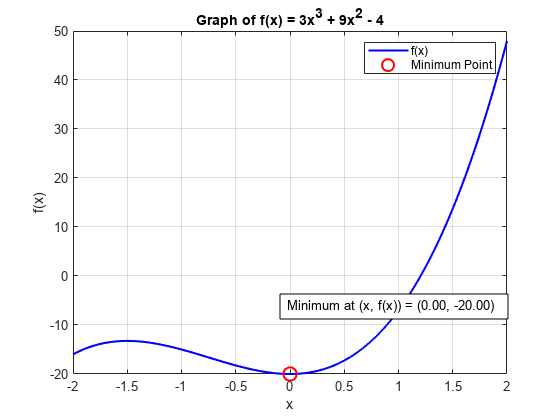



% Plotting
x_vals = linspace(min_point-2, min_point+2, 400); % Create an array of x values centered around the minimum for plotting
y_vals = f(x_vals);

figure; % Create a new figure
plot(x_vals, y_vals, 'b-', 'LineWidth', 1.5); % Plot the function
hold on;
plot(min_point, min_val, 'ro', 'MarkerSize', 10, 'LineWidth', 1.5); % Plot the minimum point

xlabel('x');
ylabel('f(x)');
title('Graph of f(x) = 3x^3 + 9x^2 - 4');
legend('f(x)', 'Minimum Point');
grid on;
% Annotating the minimum value and point on the plot
str = sprintf('Minimum at (x, f(x)) = (%.2f, %.2f)', min_point, min_val);
annotation('textbox', [0.5, 0.2, 0.3, 0.1], 'String', str, 'FitBoxToText', 'on', 'BackgroundColor', 'white', 'EdgeColor', 'black');

### **Basic optimality condition – n variables**

- Let $x^*$ be a local minimum. Then, at a point $x^*+h$ we have, by Taylor’s Theorem:

                    
$$F(x^*+h)=F(x^*)+h^T\nabla F(x^*)+\frac{1}{2}h^T\nabla^2F(x^*)h+ \cdots$$


- Here, $\nabla F$(Grad $F$) and $\nabla^2 F$(Hessian Matriz of $F$) are given by:

                       
$$\nabla F={\left[\begin{array}{c}
\frac{\partial F}{\partial x_1 }\\
\frac{\partial F}{\partial x_2 }\\
\vdots \\
\frac{\partial F}{\partial x_n }
\end{array}\right]}$$
             
$$\nabla^2 F={\left[\begin{array}{cccc}
\frac{\partial^2 F}{\partial x_1^2 } & \frac{\partial^2 F}{\partial x_1 \partial x_2 } & \cdots  & \frac{\partial^2 F}{\partial x_1 \partial x_n }\\
\frac{\partial^2 F}{\partial x_2 \partial x_1 } & \frac{\partial^2 F}{\partial x_2^2 } &  & \\
\vdots  &  & \ddots  & \vdots \\
\frac{\partial^2 F}{\partial x_n \partial x_1 } &  & \cdots  & \frac{\partial^2 F}{\partial x_n^2 }
\end{array}\right]}$$


- Consider the case for a 3-dimensional function, i.e. $n=3$. Hence $x = [x_1 \quad x_2 \quad x_3]^T$ and:

                    $F\left(x^* +h\right)=F\left(x^* \right)+\left\lbrack h_1 \;\;h_2 \;\;h_3 \right\rbrack$${\left[\begin{array}{c}
\frac{\partial F}{\partial x_1 }\\
\frac{\partial F}{\partial x_2 }\\
\frac{\partial F}{\partial x_3 }
\end{array}\right]}$ $+\frac{1}{2}\left\lbrack h_1 \;\;h_2 \;\;h_3 \right\rbrack$${\left[\begin{array}{ccc}
\frac{\partial^2 F}{\partial x_1^2 } & \frac{\partial^2 F}{\partial x_1 \partial x_2 } & \frac{\partial^2 F}{\partial x_1 \partial x_3 }\\
\frac{\partial^2 F}{\partial x_2 \partial x_1 } & \frac{\partial^2 F}{\partial x_2^2 } & \frac{\partial^2 F}{\partial x_2 \partial x_3 }\\
\frac{\partial^2 F}{\partial x_3 \partial x_1 } & \frac{\partial^2 F}{\partial x_3 \partial x_2 } & \frac{\partial^2 F}{\partial x_3^2 }
\end{array}\right]}$${\left[\begin{array}{c}
h_1 \\
h_2 \\
h_3 
\end{array}\right]}$+ ...

- Note that this can be expressed as follows:

                    
$$F\left(x^* +h\right)=F\left(x^* \right)+\sum_{i=1}^3 h_i \frac{\partial F}{\partial x_i }+\frac{1}{2}\sum_{i=1}^3 \sum_{j=1}^3 h_i h_j \frac{\partial^2 F}{\partial x_i \partial x_j }+\textrm{...}$$


- For $||h||$ sufficiently small, $F(x^*+h)-F(x^*)$ cannot be $<0$, by definition of a local minimum.

- Hence, we can deduce that $\nabla F(x^*)=0$, i.e. a vector of zeros. If this wasn’t the case, then we could choose a value of $h$ that would make $F(x^*+h)-F(x^*)$ negative!

- Therefore the sign of $F(x^*+h)-F(x^*)$ is determined by: $\frac{1}{2}h^T\nabla^2F(x^*)h$.

- Hence, to ensure a local minimum the term $\frac{1}{2}h^T\nabla^2F(x^*)h$ must be $\geq0$ for all $h$ for which $||h||$ is sufficiently small.

- Hence the Hessian matrix at $x^*$must be **positive definite**. 

- Therefore, **a sufficient condition for a local minimum for an **$n$**-variable continuous, differentiable function** is:

                $\nabla F(x^*) =0$ and $\nabla^2F(x^*)$ is positive definite.

- Note that $\nabla^2F$ is an $n \times n$ symmetric matrix because:

                $\nabla^2 F_{ij} =\nabla^2 F_{ji}$, i.e.: $\frac{\partial^2 F}{\partial x_i \partial x_j }=\frac{\partial^2 F}{\partial x_j \partial x_i }$.

### **A note on positive definite matrices**

- A positive definite matrix $P$ has the property

                $z^T P z > 0$ if $P$ is an $n \times n$ matrix and $z$ is any non-null n-vector. 

- For example, consider the matriz $A=$${\left[\begin{array}{cc}
1 & 0\\
0 & 2
\end{array}\right]}$, hence $n=2$ and:

                                
$$\left\lbrack \begin{array}{cc}
z_1  & z_2 
\end{array}\right\rbrack {\left[\begin{array}{cc}
1 & 0\\
0 & 2
\end{array}\right]}{\left[\begin{array}{c}
z_1 \\
z_2 
\end{array}\right]}=z_1^2 +\textrm{2}z_2^2 >\textrm{0}\;\textrm{,}\;z\not= 0$$


- Therefore $A$ is positive definite.

- Now consider $B=$${\left[\begin{array}{cc}
1 & 2\\
3 & 4
\end{array}\right]},$hence $n=2$ and:

                
$$\left\lbrack \begin{array}{cc}
z_1  & z_2 
\end{array}\right\rbrack {\left[\begin{array}{cc}
1 & 2\\
3 & 4
\end{array}\right]}{\left[\begin{array}{c}
z_1 \\
z_2 
\end{array}\right]}={\left[\begin{array}{cc}
z_1 +\textrm{3}z_2  & \textrm{2}z_1 +\textrm{4}z_2 
\end{array}\right]}\ {\left[\begin{array}{c}
z_1 \\
z_2 
\end{array}\right]}=\left(z_1^2 +\textrm{3}z_1 z_2 \right)+\left(\textrm{2}z_1 z_2 +\textrm{4}z_2^2 \right)=z_1^2 +\textrm{5}z_1 z_2 +\textrm{4}z_2^2$$


- If we take $z_1=-2$ and $z_2=1$, this gives a value of $-2$ which is $< 0$. Hence $B$ is not a positive definite matrix.

## Example

Determine the minimum point(s) for the following function:


$$f\left(x\right)=x_1^2 +x_2^2 +x_3^2 -\textrm{4}x_1 -\textrm{8}x_2 -\textrm{12}x_3 +\textrm{100}$$


*Solution:* 

- Grad of $f(x)$ is given by:

                     
$$\nabla f={\left[\begin{array}{c}
\frac{\partial f}{\partial x_1 }\\
\frac{\partial f}{\partial x_2 }\\
\frac{\partial f}{\partial x_3 }
\end{array}\right]}={\left[\begin{array}{c}
\textrm{2}{\textrm{x}}_1 -4\\
\textrm{2}{\textrm{x}}_2 -8\\
\textrm{2}{\textrm{x}}_3 -\textrm{12}
\end{array}\right]}$$


- Solving $\nabla F = 0$ gives:  $x_1= 2$,   $x_2 = 4$,   $x_3 = 6$

- The Hessian matrix is given by:

            
$$\nabla^2 f={\left[\begin{array}{ccc}
\frac{\partial^2 f}{\partial x_1^2 } & \frac{\partial^2 f}{\partial x_1 \partial x_2 } & \frac{\partial^2 f}{\partial x_1 \partial x_3 }\\
\frac{\partial^2 f}{\partial x_2 \partial x_1 } & \frac{\partial^2 f}{\partial x_2^2 } & \frac{\partial^2 f}{\partial x_2 \partial x_3 }\\
\frac{\partial^2 f}{\partial x_3 \partial x_1 } & \frac{\partial^2 f}{\partial x_3 \partial x_2 } & \frac{\partial^2 f}{\partial x_3^2 }
\end{array}\right]}={\left[\begin{array}{ccc}
2 & 0 & 0\\
0 & 2 & 0\\
0 & 0 & 2
\end{array}\right]}$$


- We can easily show that this matrix is positive definite. Hence the point $(2, 4, 6)$ is a minimum of the function $f(x)$ and the value at this point is $44$.

*Solution using code:*

clearvars
% 1. Define the function
 f = @(x) x(1)^2 + x(2)^2 + x(3)^2 - 4*x(1) - 8*x(2) - 12*x(3) + 100

f = function_handle with value:
    @(x)x(1)^2+x(2)^2+x(3)^2-4*x(1)-8*x(2)-12*x(3)+100



% 2. Gradient of the function
 grad_f = @(x) [2*x(1) - 4; 2*x(2) - 8; 2*x(3) - 12]

grad_f = function_handle with value:
    @(x)[2*x(1)-4;2*x(2)-8;2*x(3)-12]



% 3. Hessian matrix
 Hessian = [2, 0, 0; 0, 2, 0; 0, 0, 2]

Hessian =      2     0     0
     0     2     0
     0     0     2



% 4. Check if Hessian is positive definite
isPositiveDefinite = all(eig(Hessian) > 0);

if isPositiveDefinite
    disp('The Hessian matrix is positive definite.');
else
    disp('The Hessian matrix is not positive definite.');
    return;
end

The Hessian matrix is positive definite.



% 5. Find the minimum point by setting the gradient to zero
 x_min = [2; 4; 6];

% Evaluate the function at the minimum point
f_min = f(x_min);

% Display the results
disp('Minimum point:');

Minimum point:


disp(x_min);

     2
     4
     6



disp('Minimum value:');

Minimum value:


disp(f_min);

    44



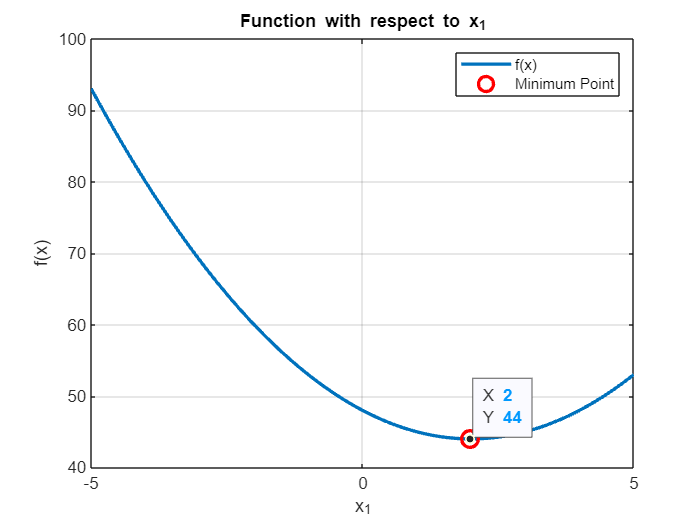


% 6. Plot the function with respect to each variable 
% and indicate minimum values

% Generate points for plotting
x1_range = linspace(-5, 5, 100);
x2_range = linspace(-5, 10, 100);
x3_range = linspace(-5, 15, 100);

% Evaluate the function over these ranges
f_x1 = arrayfun(@(x1) f([x1; x_min(2); x_min(3)]), x1_range);
f_x2 = arrayfun(@(x2) f([x_min(1); x2; x_min(3)]), x2_range);
f_x3 = arrayfun(@(x3) f([x_min(1); x_min(2); x3]), x3_range);

% Plot for x1 with other variables at their minimum
figure;
plot(x1_range, f_x1, 'LineWidth', 2);
hold on;
plot(x_min(1), f_min, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('x_1');
ylabel('f(x)');
title('Function with respect to x_1');
legend('f(x)', 'Minimum Point');
grid on;
ax = gca;
chart = ax.Children(1);
datatip(chart,2,44);

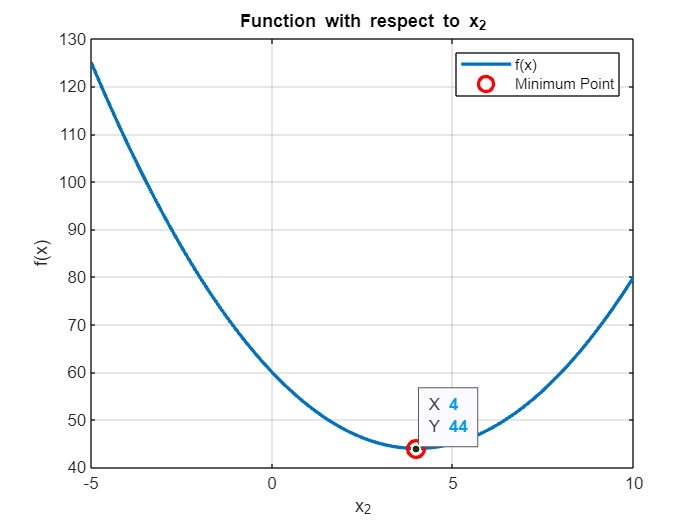


% Plot for x2 with other variables at their minimum
figure;
plot(x2_range, f_x2, 'LineWidth', 2);
hold on;
plot(x_min(2), f_min, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('x_2');
ylabel('f(x)');
title('Function with respect to x_2');
legend('f(x)', 'Minimum Point');
grid on;
ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,4,44);

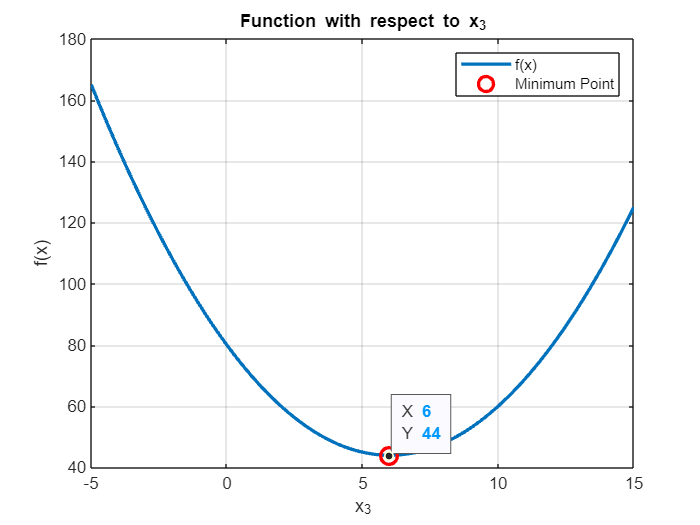


% Plot for x3 with other variables at their minimum
figure;
plot(x3_range, f_x3, 'LineWidth', 2);
hold on;
plot(x_min(3), f_min, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('x_3');
ylabel('f(x)');
title('Function with respect to x_3');
legend('f(x)', 'Minimum Point');
grid on;
ax3 = gca;
chart3 = ax3.Children(1);
datatip(chart3,6,44);

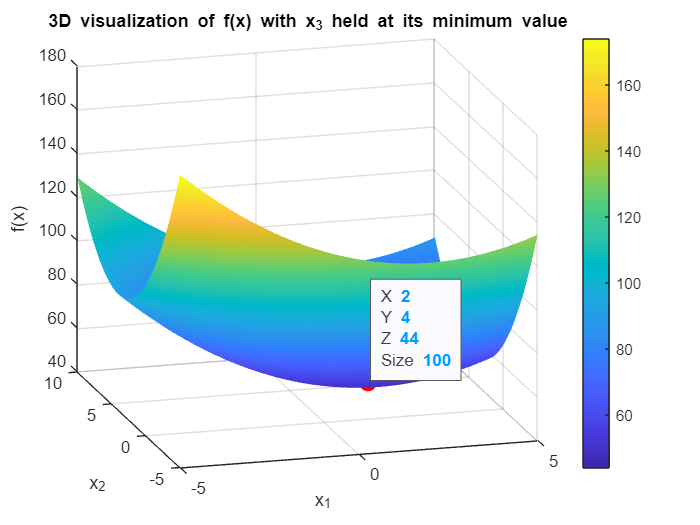



% 7. 3D Plot of the function for a slice
[x1_grid, x2_grid] = meshgrid(linspace(-5, 5, 100), linspace(-5, 10, 100));

% Calculate function values for the meshgrid
f_grid = arrayfun(@(x1, x2) f([x1; x2; x_min(3)]), x1_grid, x2_grid);

% 3D Plot
figure;
surf(x1_grid, x2_grid, f_grid, 'EdgeColor', 'none');
hold on;
scatter3(x_min(1), x_min(2), f_min, 100, 'ro', 'filled');
xlabel('x_1');
ylabel('x_2');
zlabel('f(x)');
title('3D visualization of f(x) with x_3 held at its minimum value');
colorbar;
view(-30, 40); % Adjust the view angle for better visualization
grid on;
view([-16 18])
ax4 = gca;
chart4 = ax4.Children(1);
datatip(chart4,2,4,44);

*Solution using matlab function*

clearvars -except f
% Step 1: Define the function
% Same as last solution

% Initial guess
 x0= [0; 0; 0]

x0 =      0
     0
     0




% Step 2: Use fminunc to find the minimum
options = optimset('fminunc');
options.Display = 'iter';
options.TolFun = 1e-6;
options.TolX = 1e-6;

[x_min, f_min] = fminunc(f, x0, options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4              100                            12
     1           8          82.8889      0.0833333             10  
     2          12               44              1        3.7e-06  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



% Display the results
disp('Minimum point:');

Minimum point:


disp(x_min);

    2.0000
    4.0000
    6.0000



disp('Minimum value:');

Minimum value:


disp(f_min);

   44.0000

